# Statistical Significance of Mean Values from Two Distributions

by Nithin Sivadas

For Luisa Capannolo, Date: 07/07/2021

wave=cell2mat(load_ascii_files("G:\My Drive\Research\Projects\Collaborations\Capannolo Luisa\Capannolo_2021\wavedriven_angles.txt",'%f',0));
css = cell2mat(load_ascii_files("G:\My Drive\Research\Projects\Collaborations\Capannolo Luisa\Capannolo_2021\cssdriven_angles.txt",'%f',0));

## Two-Sample Kolmogorov-Smirov Test

The Kolmogorov Smrinov test, is a statistical test that checks if the two samples are from the same underlying distribution. The null hypothesis, $H_0$ is that the two samples are from the same distribution. The p-value gives you the false positive rate of saying that the two samples came from different distributions ($\left.H_1 \right)$. In principle, you want this p-value to be very small. Practically, we need to decide how much false positive rate we can tolerate. Usually, this threshold is about 5%. You can set different thresholds below. If the false postive rate of thinking $H_1$is true $\to \;$ $p<5%$, then we can reject $H_0$ with confidence and say $H_1$ is true. Our desired result is that $H_0$ is False. If $p>5%$, then we will have to conclude that the two samples are likely from the same distirbution, we cannot say for sure that $H_1$ is true, and that our samples are not statistically significant enough to say they are from different distributions.   

Threshold = 5/100;
[h,p,ks2stat]=kstest2(wave,css,'Alpha',0.05);
disp(['The p-value from the kstest is ',num2str(p.*100,2),'%']);
if p<Threshold

The p-value from the kstest is 8.4%


    disp(['As p-value ',num2str(p.*100,3),'% < ',num2str(Threshold.*100,3),'%']);
    disp('H0 is False. i.e., The wave-driven and CSS-driven samples are from different distributions.');
else
    disp(['As p-value ',num2str(p.*100,3),'% >= ',num2str(Threshold.*100,3),'%']);
    disp('H0 is True. i.e., The wave-driven and CSS-driven samples are from the same distribution.')
end  

As p-value 8.41% >= 5%


H0 is True. i.e., The wave-driven and CSS-driven samples are from the same distribution.


References: 

- Good explanation [here](https://win-vector.com/2020/02/11/monitoring-for-changes-in-distribution-with-resampling-tests/amp/). 

- [Wiki](https://en.wikipedia.org/wiki/Kolmogorov%E2%80%93Smirnov_test#Two-sample_Kolmogorov%E2%80%93Smirnov_test)

## Permutation Test

The permutation test is a nonparameteric statistical signifance test where the distribution of the *test statistic* under the null hypothesis is obtained by calculating all possible values of teh test statistic under all possible rearrangements of the data points. In our case the *test statistic* is the difference in the mean values of tail-angles between CSS-driven and Wave-driven events. And the null hypothesis, as in the K-S Test above, is $H_0$= the two samples are from the same distribution, therefore the difference in their means is 0. The definition of $p-\textrm{value}$ is the same as above. And our desired result is that $p-\textrm{value}$ be less than the threshold (usually $5%$). Large p-values imply that the difference in the mean angles are NOT statistically significant.  

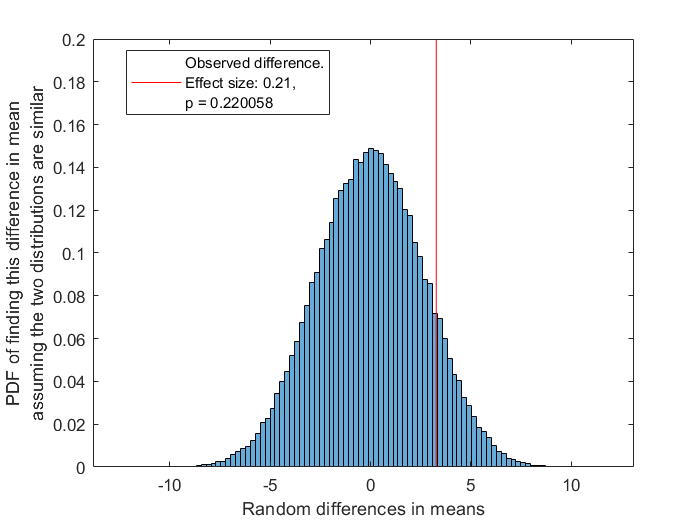

[p1,obsdiff,effSize]=permutationTest(wave,css,100000,'plotresult',1,'showprogress',250);
ylabel({'PDF of finding this difference in mean','assuming the two distributions are similar'});

disp(['The p-value from the permutation test is ',num2str(p1.*100,2),'%']);

The p-value from the permutation test is 22%


if p1<Threshold
    disp(['As p-value ',num2str(p1.*100,3),'% < ',num2str(Threshold.*100,3),'%']);
    disp('H0 is False. i.e., The mean of the wave-driven and CSS-driven samples are from different distributions, hence their difference is likely non-zero.');
else
    disp(['As p-value ',num2str(p1.*100,3),'% >= ',num2str(Threshold.*100,3),'%']);
    disp('H0 is True. i.e., The mean of the wave-driven and CSS-driven samples are from the same distribution, hence their difference is likely 0.')
end

As p-value 22% >= 5%


H0 is True. i.e., The mean of the wave-driven and CSS-driven samples are from the same distribution, hence their difference is likely 0.


References:

- [Visual explanation of permutation tests by Jared Wilber, March 2019. ](https://www.jwilber.me/permutationtest/#)

- Wiki

## Anderson-Darling (AD) test

The two-sample Anderson-Darling (AD) test of goodness of fit as a tool for comparing distributions, response time distributions in particular.The AD test is more powerful: when comparing two distributions that vary (1) in shift only, (2) in scale only, (3) in symmetry only, or (4) that have the same mean and standard deviation but differ on the tail ends only, the AD test proves to detect differences better than the KS test. In addition, the AD test has a type I error rate corresponding to alpha whereas the KS test is overly conservative. Finally, the AD test requires less data than the KS test to reach sufficient statistical power. [[Engmann and Cousineau, 2011]](http://www.jaqm.ro/issues/volume-6,issue-3/pdfs/1_engmann_cousineau.pdf)

[h3, adstat, critvalue] = adtest2(css', wave', 0.05);
if h3==1
    disp(['The AD statistics is ',num2str(adstat,3)]);
    disp('H0 is False. i.e., The mean of the wave-driven and CSS-driven samples are from different distributions, hence their difference is likely non-zero.');
else
    disp(['The AD statistics is ',num2str(adstat,3)]);
    disp('H0 is True. i.e., The mean of the wave-driven and CSS-driven samples are from the same distribution, hence their difference is likely 0.')

The AD statistics is 2.03


H0 is True. i.e., The mean of the wave-driven and CSS-driven samples are from the same distribution, hence their difference is likely 0.


end

## External Functions

function [p, observeddifference, effectsize] = permutationTest(sample1, sample2, permutations, varargin)
% parsing input
p = inputParser;
addRequired(p, 'sample1', @isnumeric);
addRequired(p, 'sample2', @isnumeric);
addRequired(p, 'permutations', @isnumeric);
addParamValue(p, 'sidedness', 'both', @(x) any(validatestring(x,{'both', 'smaller', 'larger'})));
addParamValue(p, 'exact' , 0, @isnumeric);
addParamValue(p, 'plotresult', 0, @isnumeric);
addParamValue(p, 'showprogress', 0, @isnumeric);
parse(p, sample1, sample2, permutations, varargin{:})
sample1 = p.Results.sample1;
sample2 = p.Results.sample2;
permutations = p.Results.permutations;
sidedness = p.Results.sidedness;
exact = p.Results.exact;
plotresult = p.Results.plotresult;
showprogress = p.Results.showprogress;
% enforcing row vectors
if iscolumn(sample1), sample1 = sample1'; end
if iscolumn(sample2), sample2 = sample2'; end
allobservations = [sample1, sample2];
observeddifference = nanmean(sample1) - nanmean(sample2);
pooledstd = sqrt(  ( (numel(sample1)-1)*std(sample1)^2 + (numel(sample2)-1)*std(sample2)^2 )  /  ( numel(allobservations)-2 )  );
effectsize = observeddifference / pooledstd;
w = warning('off', 'MATLAB:nchoosek:LargeCoefficient');
if ~exact && permutations > nchoosek(numel(allobservations), numel(sample1))
    warning(['the number of permutations (%d) is higher than the number of possible combinations (%d);\n' ...
        'consider running an exact test using the ''exact'' argument'], ...
        permutations, nchoosek(numel(allobservations), numel(sample1)));
end
warning(w);
if showprogress, w = waitbar(0, 'Preparing test...', 'Name', 'permutationTest'); end
if exact
    % getting all possible combinations
    allcombinations = nchoosek(1:numel(allobservations), numel(sample1));
    permutations = size(allcombinations, 1);
end
% running test
randomdifferences = zeros(1, permutations);
if showprogress, waitbar(0, w, sprintf('Permutation 1 of %d', permutations), 'Name', 'permutationTest'); end
for n = 1:permutations
    if showprogress && mod(n,showprogress) == 0, waitbar(n/permutations, w, sprintf('Permutation %d of %d', n, permutations)); end

    % selecting either next combination, or random permutation
    if exact, permutation = [allcombinations(n,:), setdiff(1:numel(allobservations), allcombinations(n,:))];
    else, permutation = randperm(length(allobservations)); end

    % dividing into two samples
    randomSample1 = allobservations(permutation(1:length(sample1)));
    randomSample2 = allobservations(permutation(length(sample1)+1:length(permutation)));

    % saving differences between the two samples
    randomdifferences(n) = nanmean(randomSample1) - nanmean(randomSample2);
end
if showprogress, delete(w); end
% getting probability of finding observed difference from random permutations
if strcmp(sidedness, 'both')
    p = (length(find(abs(randomdifferences) > abs(observeddifference)))+1) / (permutations+1);
elseif strcmp(sidedness, 'smaller')
    p = (length(find(randomdifferences < observeddifference))+1) / (permutations+1);
elseif strcmp(sidedness, 'larger')
    p = (length(find(randomdifferences > observeddifference))+1) / (permutations+1);
end
% plotting result
if plotresult
    figure;
    if verLessThan('matlab', '8.4')
        % MATLAB R2014a and earlier
        hist(randomdifferences, 20);
    else
        % MATLAB R2014b and later
        histogram(randomdifferences, 100,'Normalization','pdf');
    end
    hold on;
    xlabel('Random differences in means');
    ylabel('pdf')
    hold on;
    od = plot([observeddifference,observeddifference], [0,0.2], '-r', 'DisplayName', sprintf('Observed difference.\nEffect size: %.2f,\np = %f', effectsize, p));
    legend(od,'Location','best');
end
end

%%
function [H, adstat, critvalue] = adtest2(sample1, sample2, alpha)

if nargin < 2, error('Call adtest2 with at least two input arguments'); end
if nargin < 3, alpha = 0.05; end
% Assignment of critical value depending on alpha
if alpha == 0.01, critvalue = 3.857;
elseif alpha == 0.05, critvalue = 2.492;
elseif alpha == 0.1, critvalue = 1.933;
else error('Alpha must be either 0.01, 0.05 or 0.1.');
end
samplecomb = sort([sample1 sample2]);
ad = 0;
for i = 1:length(samplecomb)-1
m = length(find(sample1(:)<=samplecomb(i)));
ad = ad + (((m*length(samplecomb) - length(sample1)*i)^2)/(i*(length(samplecomb)-i)));
end
adstat = ad/(length(sample1)*length(sample2));
if adstat > critvalue, H = 1; else H = 0; end
end